# Optimizing Gemm

This Live Script helps you visualize the performance of the implementation of matrix-matrix multiplication.

To gather the performance data, execute 'make test_<your implementation>' in the command window.

clear

When completed, this creates output file 'output_data_GemmPJI_Ger.m' with timing data.  This Life Script then creates graphs from that timing data.

## Load timing data

It is important that in the below you enter the name of the output file created by your implementation.

% output_data_GemmJI_Kernel_MRxNR
% output_data_GemmIJP_JI_Kernel_MRxNR
output_data_GemmFiveLoops_4x4
% output_data_GemmFiveLoops_12x4

## Make sure you are getting the right answer

In the output file, for each execution of your implementation, timing data is collected as well as how close the answer is to the answer attained by the reference implementation.  Here we look at the maximum difference over all experiments.  This should be somewhere on the order of 1e-11  or smaller.  Notice that you can expect some difference between the two implementations, due to round-off error and the order in which computations are performed.

MaxAbsDiff = max( abs( data_Gemm( :, 3 ) ) )

MaxAbsDiff = 1.5348e-12

if ( MaxAbsDiff > 1.0e-10 )
    disp( 'Hmmm, better check if there is an accuracy problem' );
else
    disp( 'It appears all is fine' );
end

It appears all is fine


## Step 3: Plot performance.

We often view the rate at which routines compute rather than the time required for completing the computation.

When all matrices are $n \times n$, we know that a matrix-matrix  multiplication$ A B + C$ requires $2n^3$ floating point operations (flops).  This means that the number of operations performed per second is given by ${2 n^3}/{t}$ flops, where $t$ is the time, in seconds, for computing the multiplication.  Now, a typical current core can perform billions of flops per second, so instead we report performance in GFLOPS/sec. (billions of flops per second): ${2 n^3}/{t} \times 10^{-9}$.  This performance data is already computed in the fourth column of array "data_Gemm".

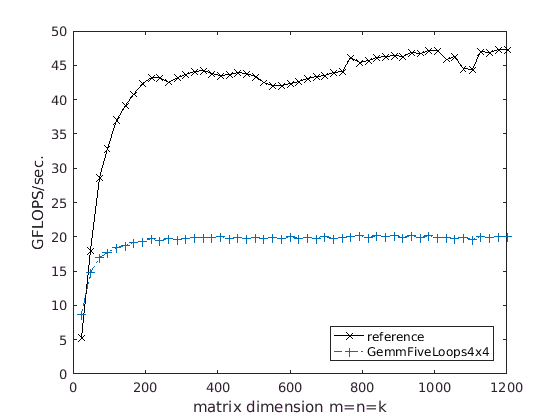

plot( data_ref( :, 1 ), data_ref( :, 3 ), 'k-x' );   % Plot the performance data for the reference implementation

hold all
 % Plot the performance data for your implementation implementation
plot( data_Gemm( :, 1 ), data_Gemm( :, 4 ), '-.+' ); 

xlabel( 'matrix dimension m=n=k' );
ylabel( 'GFLOPS/sec.' );
legend( 'reference', ...
        your_version, ...
        'Location', 'SouthEast' );
    
% Adjust the x axis
v = axis;     % extract the current ranges
axis( [ 0 v(2) 0 v(4) ] )  % start the x axis and y axis at zero